dr = 1;
R_a = 47;
% R_b = 100:dr:5*10^6;
R_b = logspace(2, 7);
uC = [1 2.2 3.3 4.7 10] .* 10^-6;
nC = [1 2.2 4.7 10 22 47 100 220 470] .* 10^-9;
pC = [1 2.2 4.7 10 22 47 100 220 470] .* 10^-12;
test_C = [0.47 1 2.2 4.7 10 47 100 220 470 1000] .* 10^-9;
R_E12 = [1 1.2 1.5 1.8 2.2 3.3 3.9 4.7 5.6 6.8 8.2];
R_E6 = [1 2.2 3.3 4.7 6.8];
R_E3 = [1 2.2 4.7];


## Frequency

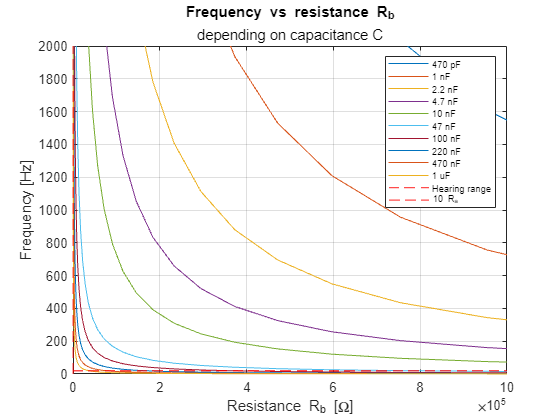

for c = test_C(1:size(test_C, 2))
    if c >= 10^-6
        c_legend = join([string(c * 10^6) "uF"]);
    elseif c >= 10^-9
        c_legend = join([string(c * 10^9) "nF"]);
    else
        c_legend = join([string(c * 10^12) "pF"]);
    end

    T = period(R_a, R_b, c);
    frequency = 1./T;
    plot(R_b, frequency, "DisplayName", c_legend);
    % loglog(R_b, frequency, "DisplayName", c_legend);
    % semilogx(R_b, frequency, "DisplayName", c_legend);
    % semilogy(R_b, frequency);
    grid on;
hold on;
end
title("Frequency vs resistance R_b")
subtitle("depending on capacitance C")
xlabel("Resistance R_b [\Omega]")
ylabel("Frequency [Hz]")
yline(20000, "Color","red", "LineWidth", 1, "LineStyle","--", "DisplayName", "Hearing range");
yline(20, "Color","red", "LineWidth", 1, "LineStyle","--", "HandleVisibility","off");
xline(R_a .* 10,  "Color","red", "LineWidth", 1, "LineStyle","--", "DisplayName", "10 R_a");
legend("Location","northeast", FontSize=7)
ylim([0 2000]);
xlim([0 1000000])
hold off;
print('../latex/img/fr_plot', '-depsc');

## notes

A_4 = 440;
note_names = ["C", "C#", "D", "D#", "E", "F", "F#", "G", "G#", "A", "A#", "B"];
keyboard_notes = ["A", "A#", "B", "C", "C#", "D", "D#", "E", "F", "F#", "G", "G#", "A", "A#", "B", "C", "C#", "D", "D#", "E"];
c = 22 * 10^-9;
r_b = 1000:2*10^6;
r_a = 220;
notes = MIDInote(57:76);
% notes = MIDInote(17:76);
notes_resistance = inverse_period(notes, r_a, c);
T = period(r_a, r_b, c);
frequency = 1./T;
loglog(r_b, frequency, "DisplayName", "22 nF");
hold on;
loglog(notes_resistance, notes, ".", "DisplayName", "notes", MarkerSize=10);
legend("Location","southwest")
yline(20000, "Color","red", "LineWidth", 0.5, "LineStyle","--", "DisplayName", "Hearing range");
yline(20, "Color","red", "LineWidth", 0.5, "LineStyle","--", "HandleVisibility","off");
ylim([18 22000]);
grid on;
hold off;

## notes diffrence

notes_resistance_difference = 1:size(notes_resistance-1, 2);
notes_nearest_resistor = 1:size(notes_resistance-1, 2);
% notes_resistance_difference(1) = notes_resistance(1);
for r_multiplier = [1 10 100 1000 10000 100000 1000000]
    for k = 1:size(notes_resistance_difference, 2)
        if k >= 20
            break
        end
        notes_resistance_difference(k) = notes_resistance(k) - notes_resistance(k+1);
        temp = interp1(R_E12 .* r_multiplier, R_E12 .* r_multiplier, notes_resistance_difference(k), "nearest");
        if temp >= 0
            notes_nearest_resistor(k) = temp; 
        end
    end
end
bar_plot = [notes_resistance_difference; notes_nearest_resistor]
bar(bar_plot')

## testing

test_bar = [add_array(notes_resistance_difference); add_array(notes_nearest_resistor)]
bar(test_bar');